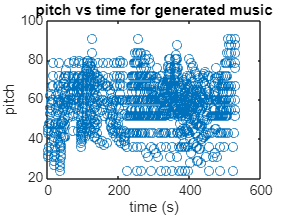

% sound analysis
generatedMidi = readmidi("D:\TANVI_COLLEGE_FILES\ESMT_PROJECT_SEM5\maestro-v3.0.0-midi\maestro-v3.0.0\2004\MIDI-Unprocessed_SMF_02_R1_2004_01-05_ORIG_MID--AUDIO_02_R1_2004_06_Track06_wav.midi");

% extract pitch, time and duration columns
pitchColumn = 4;
timeColumn = 1;
durationColumn = 7;

pitchData = generatedMidi(:, pitchColumn);
timeData = generatedMidi(:, timeColumn);
durationData = generatedMidi(:, durationColumn);

figure;
plot(timeData, pitchData, 'o');
title('pitch vs time for generated music');
xlabel('time (s)');
ylabel('pitch');

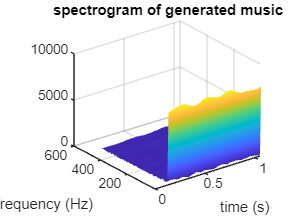


% performing spectral analysis on generated midi
% create a spectrogram to analyze
% colors represent the amplitude or intensity of a particular frequency
% brighter colors or higher peaks indicate louder frequencies
[s, f, t] = spectrogram(pitchData, 256, 250, 256, 1E3); % 1kHz sample rate for MIDI-like data
figure;
surf(t, f, abs(s));
shading interp;
title('spectrogram of generated music'); % a spectrogram is a visual representation of the strength of a signal over time at diff frequencies. used to analyze audio, vibrations and seismic signals
xlabel('time (s)');
ylabel('frequency (Hz)');